# Residual

Script to calculate STI for time series images. Optimised for smaller memory.

## Inputs & arguments

- **time series images**: The images at different dates and years (say n images).

- mask: Mask file for each year.

- **spatilal lag**: The number of pixels to expand from centroid.

## outputs:

- **STI series images**: The STI index at each pixel and date (return n-1 images).

Code:

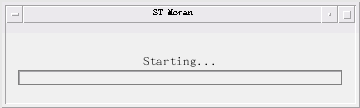

% Choose mask file.
[File, Path]=uigetfile({'*.tif'},'Choose mask file.','Multiselect','off','/home/dk/文档/Tutor/localSTMoran/其他数据与资料/');
[mask, R0] = geotiffread(strcat(Path, File));
[x,y] = size(mask);

% Choose harmonic models.
[fileH, pathH] = uigetfile({'*.tif'}, 'Choose harmonic params imagery.', 'Multiselect', 'on', '/home/dk/文档/Tutor/localSTMoran/其他数据与资料/');
[~, fileLengthH] = size(fileH);
paramsH = zeros(x,y,fileLengthH);
for num = 1:fileLengthH
    paramsH(:,:,num) = geotiffread(strcat(pathH, char(fileH(num))));
end

% Read Params.
    beta0 = paramsH(:,:,1);
    beta1 = paramsH(:,:,2);
    beta2 = paramsH(:,:,3);
    beta3 = paramsH(:,:,4);

    
% Choose time series imagery.
[file, path] = uigetfile({'*.tif'}, 'Choose imagery.', 'Multiselect', 'on', '/home/dk/文档/Tutor/localSTMoran/(第二次挑选）衡阳盆地Landsat一致性数据生成结果/image/');
[~, fileLength] = size(file);

dates= zeros(1,2);
ndvi = nan(x,y,2);
residual = nan(x,y);

% Timer and waitbar.
tic
wb = waitbar(0, 'Starting...');
set(wb,'Name','ST Moran');


% Read & mask time series images and batch NDVI.
for num = 1:fileLength
    [temp, ~] = geotiffread(strcat(path,char(file(num))));
    
    % Local variables.
    NIR = double(temp(:,:,4));
    R = double(temp(:,:,3));
    ndvi = (NIR - R) ./ (NIR + R);
    ndvi(ndvi>=1) = 1;
    ndvi(ndvi<=-1) = -1;
    ndvi(mask ~=1) = nan;
    
    % Harmonic modeling and getting residual
    DOYtemp = char(file(num));
    DOY = str2double(DOYtemp(7:end-4));
    angle = 2 * pi * DOY / 365;
    harmonic = beta0 + beta1 .* DOY + beta2 * cos(angle) + beta3 * sin(angle);
    harmonic(mask ~= 1) = nan;
    residual(:,:) = ndvi - harmonic;
    residual(~isfinite(residual)) = nan;
    
    outName = strcat('/home/dk/文档/Tutor/localSTMoran/(第二次挑选）衡阳盆地Landsat一致性数据生成结果/image/residual/','residual_',DOYtemp(3:end-4));
    geotiffwrite(outName,residual,R0,'CoordRefSysCode',32649);
end
toc

时间已过 683.217802 秒。
